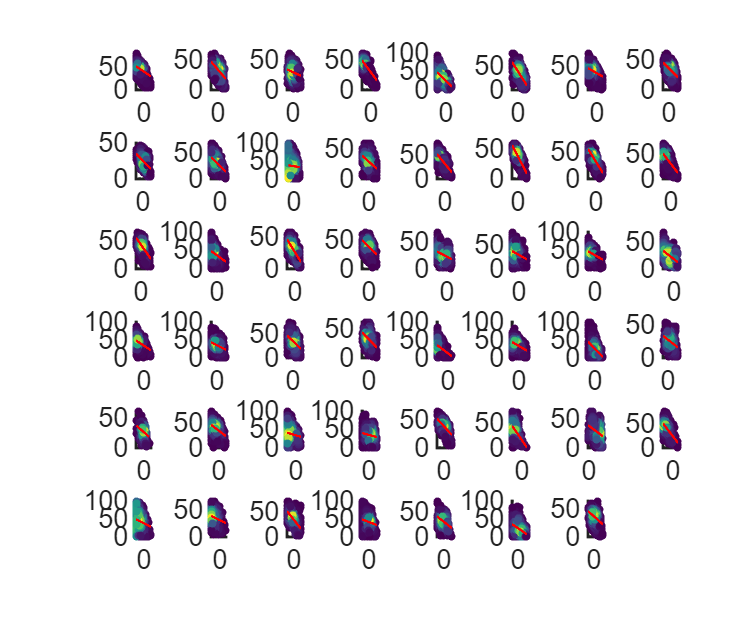

clc; clear; addpath z_toolbox;
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step4_IEDtw_TD-6d0_IT-100ms_fitting', ...
    'op5_IEDtw_ED-vs-delay_rate-vs-delay_fitting.mat'), 'rate_delay_corr');
figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
for nS = 1:47
    ED = rate_delay_corr(nS).ED;
    IEDtwD = rate_delay_corr(nS).delay;
    IEDtwR = rate_delay_corr(nS).rate;
    [~, ~, ~, Curve] = fit_polyfit(IEDtwR, IEDtwD, 1, 0.05);
    subplot(6, 8, nS);
    f_densityScatter(IEDtwR, IEDtwD, 2); hold on;
    plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2);
end